# Systems Lab: Systems of ODEs in MATLAB

## Exercise 1

Objective: Write your own ODE system solver using the Heun/Improved Euler Method and compare it to `ode45`.

Details: Consider the system of 2 ODEs:

`x1'=f(t,x1,x2), x2'=g(t,x1,x2)`

This m-file should be a function which accepts as variables (t0,tN,x0,h), where t0 and tN are the start and end points of the interval on which to solve the ODE, h is the stepsize, and x0 is a vector for the initial condition of the system of ODEs `x(t0)=x0`. You may also want to pass the functions into the ODE the way `ode45` does (check MATLAB labs 2 and 3).

Your m-file should return a row vector of times and a matrix of approximate solution values (the first row has the approximation for `x1` and the second row has the approximation for `x2`).

Note: you will need to use a loop to do this exercise. You will also need to recall the Heun/Improved Euler algorithm learned in lectures. 

%See in separate function file (solvesystem_wangrush.m)

## Exercise 2

Objective: Compare Heun with an exact solution

Details: Consider the system of ODEs

`x1' = x1/2 - 2*x2, x2' = 5*x1 - x2`

with initial condition `x(0)=(1,1)`.

Use your method from Exercise 1 to approximate the solution from `t=0` to `t=4*pi` with step size `h=0.05`.

Compute the exact solution (by hand) and plot both phase portraits on the same figure for comparison.

Your submission should show the construction of the inline function, the use of your Heun's method to obtain the solution, a construction of the exact solution, and a plot showing both. In the comments, include the exact solution.

Label your axes and include a legend.

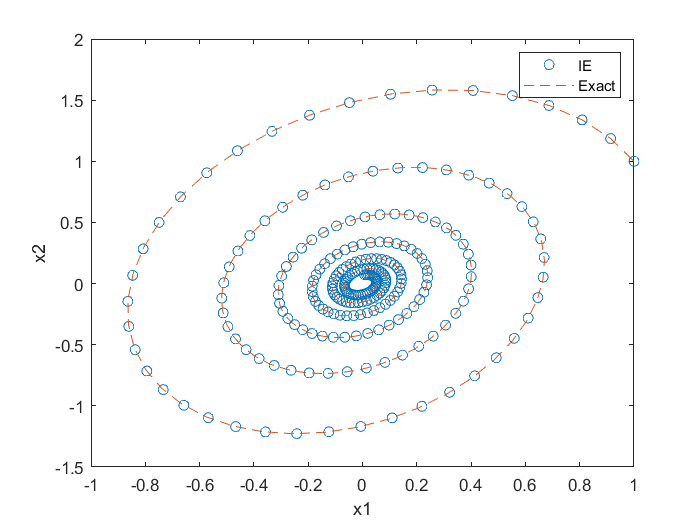

clear all;

%System of ODES Function Definitions 
f = @(t,x1,x2) x1/2 - 2*x2;
g = @(t,x1,x2) 5*x1 - x2;

x0=[1;1];
t0=0;
tN=4*pi;
h=0.05;

% Exact Solutions Computed by Hand 
% x1 = (1/151)*exp(-t/4)*(151*cos(sqrt(151)*t/4) - 5*sqrt(151)*sin(sqrt(151)*t/4))
% x2 = (1/151)*exp(-t/4)*(17*sqrt(151)*sin(sqrt(151)*t/4) + 151*cos(sqrt(151)*t/4))

%Using Improved Euler's 
[t,A] = solvesystem_wangrush(t0,tN,x0,h,f,g);
x1_ie= A.x1;
x2_ie = A.x2;

%Exact Solutions 
x1_exact = (1/151) * exp(-t/4) .* (151*cos(sqrt(151)*t/4) - 5*sqrt(151)*sin(sqrt(151)*t/4));
x2_exact = (1/151) * exp(-t/4) .* (17*sqrt(151)*sin(sqrt(151)*t/4) + 151*cos(sqrt(151)*t/4));

plot(x1_ie, x2_ie, 'o', x1_exact, x2_exact, '--');
xlabel('x1');
ylabel('x2');
legend("IE","Exact")

## Exercise 3

Objective: Compare your method with Euler's Method (from `iode`).

Details: Use `iode` to plot the solution for the same problem with the same step size as on Exercise 2.

Compare your solution on exercise 2, the exact solution from exercise 2 and the approximation using Euler's method. Plot the solution for Euler's method and make note of any differences.

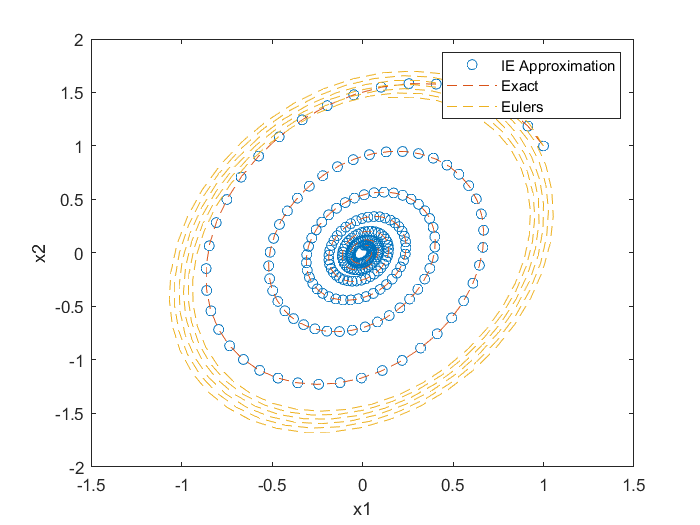

clear all;
clf;

%System of ODES Function Definitions 
f = @(t,x1,x2) x1/2 - 2*x2;
g = @(t,x1,x2) 5*x1 - x2;

x0=[1;1];
t0=0;
tN=4*pi;
h=0.05;

%Question 2 Method 
[t,A] = solvesystem_wangrush(t0,tN,x0,h,f,g);
x1_ie = A.x1;
x2_ie = A.x2;

%Eulers using matlab's iode
y = @(t, x) [x(1)./2 - 2.*x(2); 5.*x(1) - x(2)];
y_euler = euler(y, x0, t); 

%Exact Solutions 
x1_exact = (1/151) * exp(-t/4).*(151*cos(sqrt(151)*t/4) - 5*sqrt(151)*sin(sqrt(151)*t/4));
x2_exact = (1/151) * exp(-t/4).*(17*sqrt(151)*sin(sqrt(151)*t/4) + 151*cos(sqrt(151)*t/4));


plot(x1_ie, x2_ie, 'o', x1_exact, x2_exact,'--',y_euler(1,:), y_euler(2,:), '--');
xlabel('x1');
ylabel('x2');
legend('IE Approximation', 'Exact','Eulers');

% Both methods show an asymptotically stable spiral point solution, which
% result from them having complex eigenvalues. The negative real part causes the 
% inward spiral and makes it stable and the imaginary part causes the spiral. 
%Euler's is not as accurate because it does not update, the result is it does
% not end up converging to the center 